# A comparison between *D*-optimal and model-based DoE

Iván Blázquez Arenas, Pablo Carbonell, Irene Otero-Muras

## MBODoE Results for second case of study

clc;clear all;close all;

%Functions needed
addpath Model_Cases\
addpath Experimentation\
addpath MBDoE_functions\
addpath Parameter_Estimation\


## Input parameters

%% INPUTS %%

%COMMON INPUTS

% - Max number of experiments

n_max = 30;

% - Number of initial valid design seeds

seeds = 5;

% - Design Space

Lb = 0.1;
Ub = 3e5;

% - Number of factors/dimension of support point

k = 1;

%MBODoE INPUTS

% - Number of parameters in model and minimum number of experiments
% required

n_p = 2;
n_min = n_p + 1;

% % - Number of levels to consider (represent the space of design)
% 
% n_levels = 200;

% - Function with the model response, depends on experimental conditions
% and parameters value

model_response = @(x,p)Model_case_2(x,p);

% - Standard deviation of experimental Gaussian noise (Fisher weight)

sigma = 1;

% - Tolerance of bad condition design

tol = 1e-6;

% - Number of random start points in gradient optimization

n_init = 1;

% - Parameters space and number of initial values

np_init = 20;

Lb_p = [1e-9 100];
Ub_p = [1e-6 1e3];

% - Excursions

lambda = 3;

% - Unsconstrained problem considered, only design space

A = [];
b = [];
Aeq = [];
beq = [];
nonlcon = [];

% - Values needed of the stop criteria

delta = 1;   % Minimum percentage of improvement in n_comp iterations
n_comp = 5;    % "Distance" of iterations to compare

% EXPERIMENT SIMULATION INPUTS

% - Experiment parameters

p_exp = [1e-8 1e3];

% - Experiment model

model_experiment = @(x)Model_case_2(x,p_exp); %PC

% - Experiment rounds

n_rounds = 100;

% - Max.Relative Error added (+/- x%)

max_rel_error = 10;

% MODEL VALIDATION

% - Number of random points to validate

n_exp_val = 100;



## Response simulation 

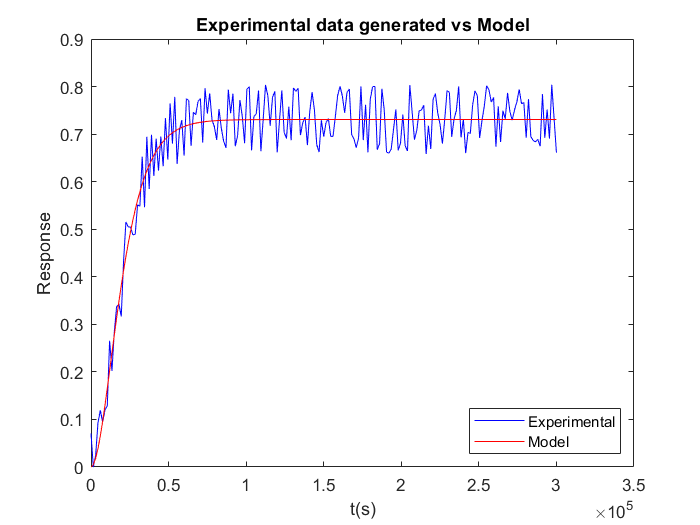

t = [0.1:1500:3e5 + 0.1];
y1 = Experiment_Simulation2(model_experiment, t', max_rel_error, 1);
y2 = Experiment_Simulation2(model_experiment, t', 0, 1);
figure(1)
plot(t,y1,'b')
hold on
plot(t,y2,'r')
hold off
title("Experimental data generated vs Model")
xlabel("t(s)")
ylabel("Response")
legend('Experimental','Model','Location','southeast')

## **Preallocating the results**

%% PROCESS %%

% - Cell structure for results

n_cases = (n_max - n_min) + 1;        % Number of cases 

results_MBDoE = cell(n_cases, 9);         

## Optimal design of experiments with MBODoE:

- Generating the random values of parameters to solve all the local problems and the data structure to save results

 % Generate the random initial parameter values
    
p_init = zeros(np_init,n_p);

for i = 1:n_p
    
    p_init(:,i) = Lb_p(i)*ones(np_init,1) + (Ub_p(i) - Lb_p(i))*rand(np_init,1);
    
end

% Generate a p_structure to save the experiments designs

p_optimal_designs = cell(np_init, seeds);
j_d_optimal_p = zeros(np_init, seeds);



- DETMAX Algorithm application for all cases (parameters and seeds, seed generated inside the function)

tic

index = 1;

for n = n_min:n_max
    
    n
    
    for j = 1:np_init    % Different parameters combination
        
        for s = 1:seeds  % Different seed values
            
            [D_opt, j_D_opt] = Detmax_Grad(model_response, p_init(j,:), k, n, sigma, tol, lambda, delta, n_comp, n_init, A, b, Aeq, beq, Lb, Ub, nonlcon);
            % Save all the local results
            
            p_optimal_designs(j,s) = {D_opt};
            j_d_optimal_p(j,s) = j_D_opt;
            
        end
    
    end
    
    % Save the best design of experiments 
    
    [best_per_col,i_rows] = max(j_d_optimal_p,[],1);
    [best_j_d, i_col] = max(best_per_col);
    i_row = i_rows(i_col);
    
    results_MBDoE(index,1) = {n};
    results_MBDoE(index,2) = {p_optimal_designs{i_row, i_col}};
    results_MBDoE(index,3) = {best_j_d};
    index = index + 1;
    
end

t_MBODoE_DETMAX = toc


### *Plots:*

- D-efficiency per number of experiments considered

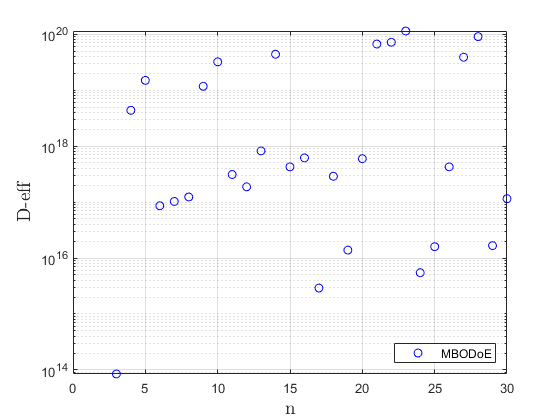

Deff_max = zeros(1, n_cases);

number_exp = n_min:n_max;

for c = 1:n_cases
    
    Deff_max(c) = results_MBDoE{c,3};
    
end

figure(2)
semilogy(number_exp,Deff_max,'bo')
%title("Max D-efficiency per number of experiments, linear model",'Interpreter','latex','FontWeight','bold','FontSize',14)
xlabel("n",'Interpreter','latex','FontWeight','bold','FontSize',14)
ylabel("D-eff",'Interpreter','latex','FontWeight','bold','FontSize',14)
grid on
legend('MBODoE','Location','southeast')

## Simulating the experiments for MBODoE designs

for index = 1:n_cases
    
    index
      
    results = Experiment_Simulation2(model_experiment, results_MBDoE{index,2}, max_rel_error, n_rounds);
    results_MBDoE(index,4) = {results};
    
end


## Estimating the parameters for MBODoE Model

tic

for index = 1:n_cases
    
    index
    
    % Loading the design and the experimental data
    
    D = results_MBDoE{index, 2};
    Y = results_MBDoE{index, 4};
    
    % Estimate the parameters of the model and the relative error comitted, one by each experimental round
    
    [p_est, err_per_round] = Parameter_Estimation_MBDoE_Grad(D, Y, model_response, n_p, n_init, [], [], [], [], Lb_p, Ub_p, []);
    
    results_MBDoE{index, 5} = p_est;
    results_MBDoE{index, 6} = err_per_round;
    
end

t_model = toc



## Validation of models

### Generating random points to test the models


Points_to_eval = zeros(n_exp_val,k);

for i = 1:k
    
    Points_to_eval(:,i) = Lb(i) + (Ub(i) - Lb(i))*rand(n_exp_val,1);
    
end

% - Experiments

Y_val = Experiment_Simulation2(model_experiment, Points_to_eval, max_rel_error, 1);

Y_span = max(Y_val) - min(Y_val);


### Model validation: Error calculations


for index = 1:n_cases
    
    index
    
    parameters_val = results_MBDoE{index,5};
    
    errors_val = zeros(1,n_rounds);
    
    % Model responses and errors calculation (all points in the round)
    
    for i_r = 1:n_rounds
                 
        Y_model = zeros(n_exp_val,1);
        
        for i_exp = 1:n_exp_val
            
            Y_model(i_exp) = model_response(Points_to_eval(i_exp,:), transpose(parameters_val(:,i_r)));
            
        end
        
        errors_val(i_r) = (100/n_exp_val)* sum(abs((Y_val - Y_model)./Y_span));
        
    end
    
    results_MBDoE{index, 7} = errors_val;
    
    % Mean of all the experimental rounds
    
    results_MBDoE{index, 8} = mean(errors_val);
    
    % Max of all the experimental rounds
    
    results_MBDoE{index, 9} = max(errors_val);
    
end


### *Plots: *Comparative between types of models

- Best model achieved vs Model of experimentation

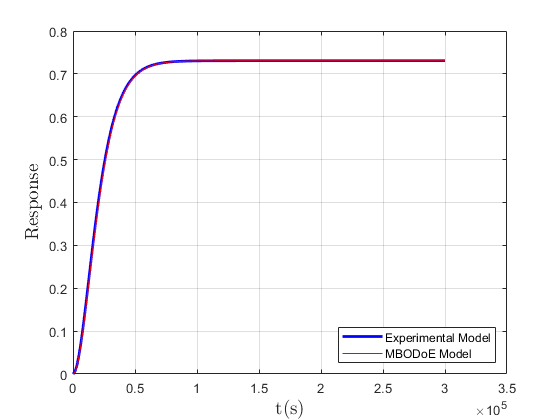

% Times of observation

t = [0.1:1500:3e5 + 0.1]';

% Values of model experiment

y_model = Experiment_Simulation2(model_experiment, t, 0, 1);

% Values of MBODoE model

% - Getting the best case

mean_errors = zeros(1,n_cases);

for i = 1:n_cases
    
    mean_errors(i) = results_MBDoE{i, 8};
    
end

[~,ind_best_case] = min(mean_errors);

% - Getting the index of the best round, maximum number of experiments

errors = results_MBDoE{ind_best_case,7};

[~,ind_best] = min(errors);

% - Getting the parameters of the model of this best round

p_rounds = results_MBDoE{ind_best_case,5};

p_best = p_rounds(:,ind_best);

% - Compute the values

y_MBODoE = zeros(length(t),1);

for i = 1:length(t)
    
    y_MBODoE(i) = model_response(t(i), transpose(p_best));
    
end

% PLOT

figure(3)
plot(t,y_model,'b','LineWidth', 2)
hold on
plot(t,y_MBODoE,'r')
hold off
%title("Models achieved vs Model of experimentation",'Interpreter','latex','FontWeight','bold','FontSize',14)
xlabel("t(s)",'Interpreter','latex','FontWeight','bold','FontSize',14)
ylabel("Response",'Interpreter','latex','FontWeight','bold','FontSize',14)
grid on
legend('Experimental Model','MBODoE Model','Location','southeast')

- Sum of error in each round of experimentation (for one case of number of experiments: n_max)

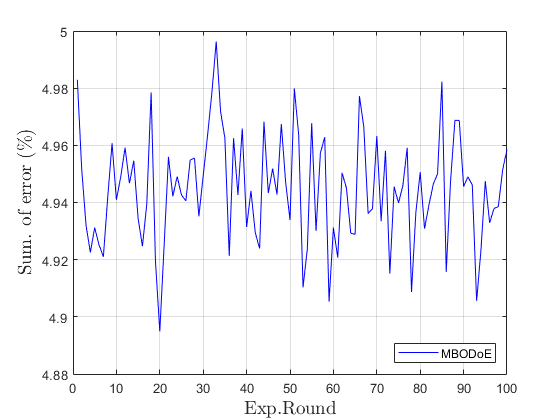

% Load of errors:

errors = results_MBDoE{ind_best_case,7};

% PLOTS

round_exp = 1:n_rounds;

figure(4)
plot(round_exp,errors,'b')
%title("Sum of relative errors in each experiments round (Maximum number of experiments), CE Algorithm",'Interpreter','latex','FontWeight','bold','FontSize',10)
xlabel("Exp.Round",'Interpreter','latex','FontWeight','bold','FontSize',14)
ylabel("Sum. of error (\%)",'Interpreter','latex','FontWeight','bold','FontSize',14)
grid on
legend('MBODoE','Location','southeast')

- Mean error of all experimental rounds per number of experiments

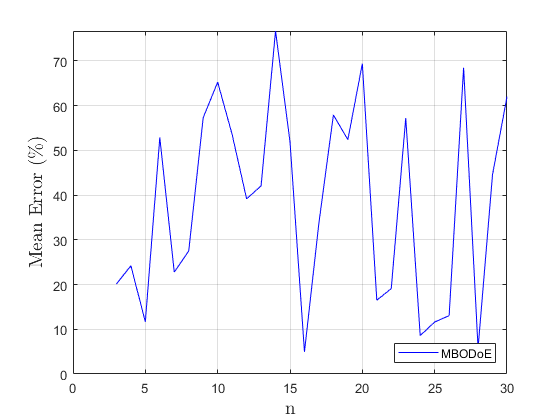

% Experiments cases

experiments = n_min:n_max;

% Load of mean error:

mean_error = zeros(1,n_cases);

for index = 1:n_cases
    
    mean_error(index) = results_MBDoE{index, 8};
    
end

% PLOT

figure(5)
plot(experiments,mean_error,'b')
ylim([0 Inf])
%title("Mean error per number of experiments, CE algorithm",'Interpreter','latex','FontWeight','bold','FontSize',10)
xlabel("n",'Interpreter','latex','FontWeight','bold','FontSize',14)
ylabel("Mean Error (\%)",'Interpreter','latex','FontWeight','bold','FontSize',14)
grid on
legend('MBODoE','Location','southeast')

- Max error of all experimental rounds per number of experiments

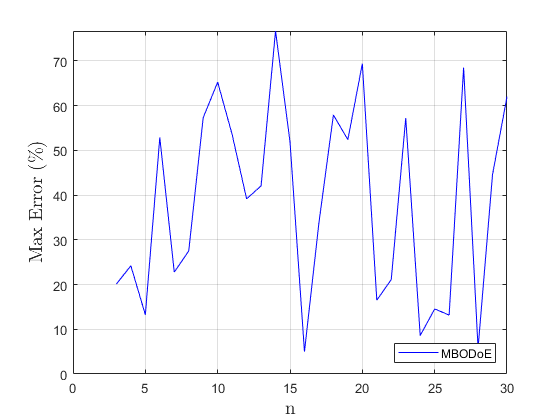

% Load of max error:

max_error = zeros(1,n_cases);

for index = 1:n_cases
    
    max_error(index) = results_MBDoE{index, 9};
    
end

% PLOT

figure(6)
plot(experiments,max_error,'b')
ylim([0 Inf])
%title("Max error per number of experiments, CE algorithm",'Interpreter','latex','FontWeight','bold','FontSize',10)
xlabel("n",'Interpreter','latex','FontWeight','bold','FontSize',14)
ylabel("Max Error (\%)",'Interpreter','latex','FontWeight','bold','FontSize',14)
grid on
legend('MBODoE','Location','southeast')